Example of dilation with a linear mapping and uniform scaling

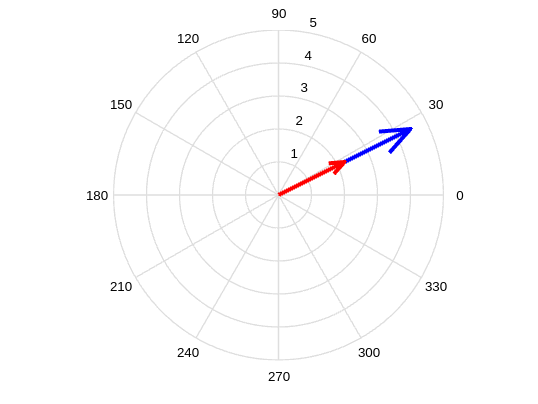

clf;
rho=2;
A=rho*eye(2);
x=[2 1]';
y=A*x;
h=compass(y(1),y(2),'b'); set(h,'LineWidth',3); hold on; axis('tight');
h=compass(x(1),x(2),'r'); set(h,'LineWidth',3);

Example of non uniform scaling

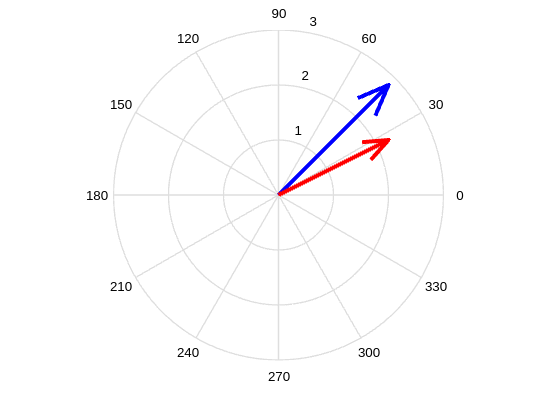

clf;
A=diag([1 2]);
x=[2 1]'; y=A*x;
h=compass(y(1),y(2),'b'); set(h,'LineWidth',3); hold on; axis('tight');
h=compass(x(1),x(2),'r'); set(h,'LineWidth',3);

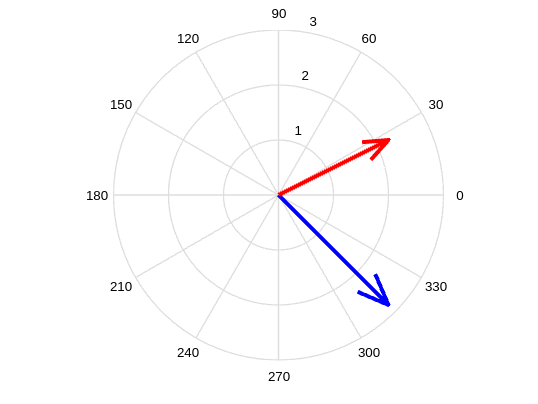


clf;
A=diag([1 -2]);
x=[2 1]'; y=A*x;
h=compass(y(1),y(2),'b'); set(h,'LineWidth',3); hold on; axis('tight');
h=compass(x(1),x(2),'r'); set(h,'LineWidth',3);

disp(y);

       2       
      -2       



A=diag([1 -1])

A =        1              0       
       0             -1       


xa=[2 -1]';
xb=[3 3]';
xc=[xa xb]

xc =        2              3       
      -1              3       


%disp(A*xa);
%disp(A*xb);
disp(A*xc); % Change the sign of the last rows

       2              3       
       1             -3       



clf;

Reflection over y axis

A=diag([-1 1])

A =       -1              0       
       0              1       


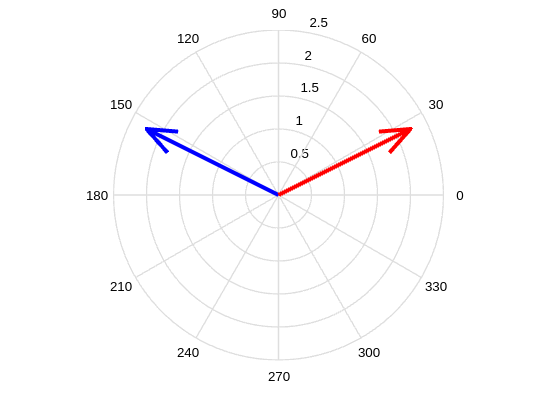

x=[2 1]'; y=A*x;
h=compass(y(1),y(2),'b');
set(h,'LineWidth',3)
hold on; axis('tight')
h=compass(x(1),x(2),'r');
set(h,'LineWidth',3)

Reflection over x -axis

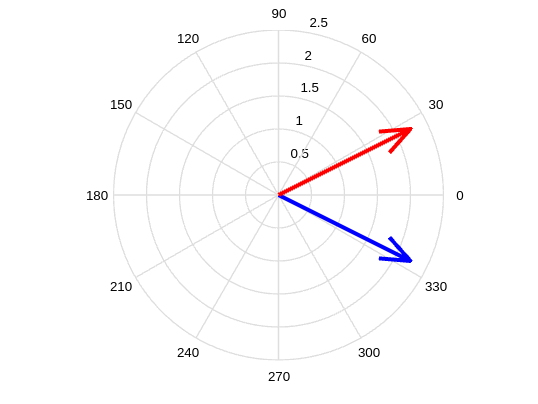

clf;
A=diag([1 -1]);
x=[2 1]'; y=A*x;
h=compass(y(1),y(2),'b');
set(h,'LineWidth',3)
hold on; axis('tight')
h=compass(x(1),x(2),'r');
set(h,'LineWidth',3)

Reflection over origin

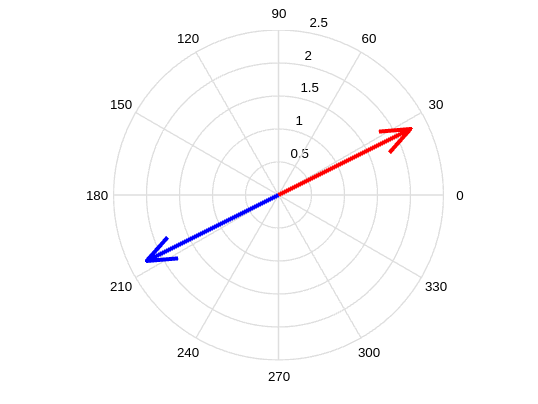

clf;
A=diag([-1 -1]);
x=[2 1]'; y=A*x;
h=compass(y(1),y(2),'b');
set(h,'LineWidth',3)
hold on; axis('tight')
h=compass(x(1),x(2),'r');
set(h,'LineWidth',3)

a=[1 0]'; syms lambda real
syms x y [2 1] real
P1=x+y-lambda*a; P2=a'*(x-y);
Y=solve(P2,P1(2),y1,y2);
y=[Y.y1;Y.y2]

$$y = \left(\begin{array}{c} x_{1}\\ -x_{2} \end{array}\right)$$


A=zeros(2);
for k=1:2
	if simplify(symvar(y(k)) == x1)
		A(k,1)=y(k)/x1;
	end
	if simplify(symvar(y(k)) == x2)
		A(k,2)=y(k)/x2;
	end
end

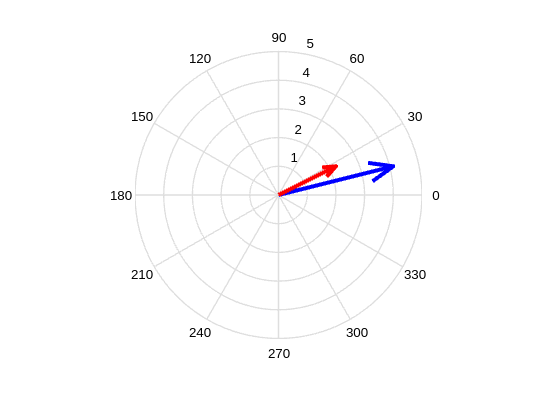

clf;
A=[1 2;0 1]; x=[2 1]'; y=A*x;
h=compass(y(1),y(2),'b'); set(h, 'LineWidth',3); hold on; grid on;
h=compass(x(1),x(2),'r'); set(h, 'LineWidth',3);

x=[-2 1]'; y=A*x;

clf;

A=[1 2;0 1]; x=[0 1]'; y=A*x

y =        2       
       1       


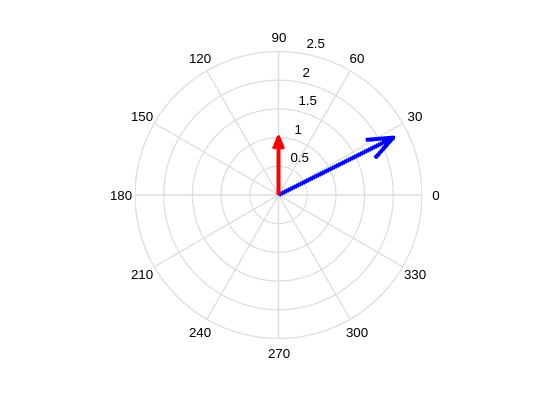

h=compass(y(1),y(2),'b'); set(h, 'LineWidth',3); hold on; grid on;
h=compass(x(1),x(2),'r'); set(h, 'LineWidth',3);


th=acos(dot(x,y)/(norm(x)*norm(y))); disp(tan(th));

       2       



clf;

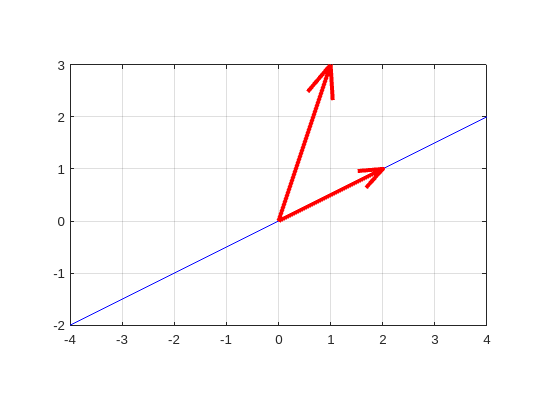

clf;
a=[2 1]'; syms b real; r=b*a; A=[a*a'/norm(a)^2];
x=[1 3]'; y=A*x; n=null(a'); % normal
fplot(r(1),r(2),[-2 2],'Color','b'); hold on
h=compass([x(1) y(1)],[x(2) y(2)] ,'r'); set(h, "LineWidth",3); hold on;
axis equal; grid on;

fplot(a(1)+n(1),a(2)+n(2), [-1 2.5],'Color','c','LineStyle','--');

Error using fplot
Invalid parameter '1.8944'.